# ODEFUN for Systematic Reductions Model

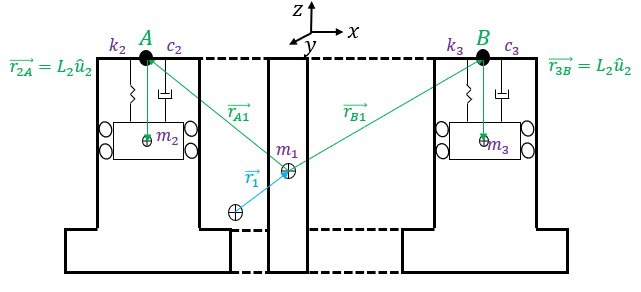

Impliment the differential equation of interest using state space representation

function xdot = odefun_noPTO_reg(t,x,body,BEM,waveData)

## Unpack the problem struct()                                  

m1 = body.m1;               
J1 = body.J1;                               

A = BEM.A;

Fex = BEM.Fex;
F11_re = Fex.real.Fex11_re;     
F33_re = Fex.real.Fex33_re;     
F55_re = Fex.real.Fex55_re;
F11_im = Fex.imag.Fex11_im;     
F33_im = Fex.imag.Fex33_im;     
F55_im = Fex.imag.Fex55_im;

h_wave = waveData.h_wave;
w_wave = waveData.w_wave;
t_ramp = waveData.t_ramp;

## Assign variable names to "x" vector

x1 = x(1);
z1 = x(2);
theta = x(3);

x1_dot = x(4);
z1_dot = x(5);
theta_dot = x(6);

## Calculate forces and mass matrix

[f_b,f_rad] = calculate_restoring_and_damping([x1;z1;theta],[x1_dot;z1_dot;theta_dot],BEM);
Fex_reg = excitation_force_regular_3DOF(F11_im,F11_re,F33_im,F33_re,F55_im,F55_re,h_wave,t,w_wave);

M = [m1 0 0
     0 m1 0;
     0 0 J1];

M = M + A;

## Calculate ramp function

if t/t_ramp < 1
    ramp = (1/2)*(1+cos(pi+pi*(t/t_ramp)));
else
    ramp = 1;
end

## Format output 

xdot = zeros(6,1);
xdot(1:3) = x(4:6);
xdot(4:6) = M\(f_b + f_rad + Fex_reg*ramp);
end